## dePillisSoln

The goal of this code is to reproduce Figures 6-14 of L. G. de Pillis, W. Gu, and A. E. Radunskaya. 2006. Mixed immunotherapy and chemotherapy of tumors: modeling, applications and biological interpretations. J Theoretical Biology 238 (4):841-62. [doi: 10.1016/j.jtbi.2005.06.037](https://pubmed.ncbi.nlm.nih.gov/16153659/)

First, choose a scenario from the list below to reproduce. Note that the authors didn't label their subfigures. We assumed the labeling was left to right, top to bottom for a, b, c, d, etc.

scenario = "Fig13a";

Select "Hide Code" option on the right panel to directly see the results of choosing various scenarios. Note that any discrepancies from the de Pillis et al. results are noted in the figure title. 

If the figure legend ever covers a portion of the curves that you are interested in, you can click and drag it to another location.

Explore each scenario and compare to the figures in de Pillis et al. For the scenarios that don't match the expected results, explore the code to see the effects of various parameters to see if you can improve the agreement between these solutions and the published results.

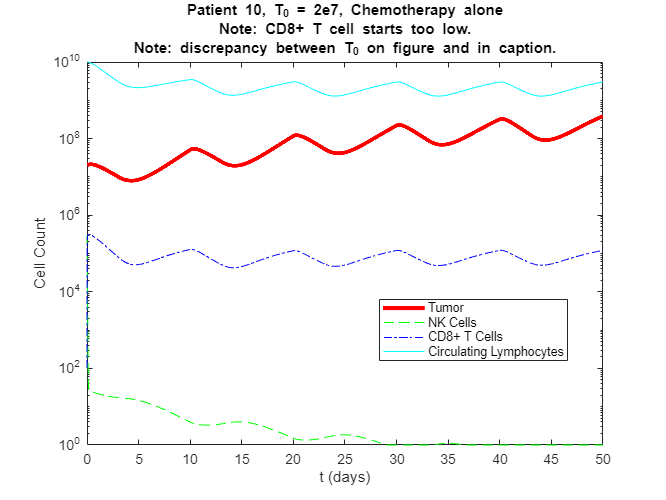

close all
% Defining t range and intervals 
t0 = 0;
tf = 120;
trange =linspace(t0, tf, 5001);

% default values for Fig6a
T0 = 1e6;
C0 = 1.1e7; 
L0 = 100; 
N0 = 5e4;
M0 = 0;
I0 = 0;
ylimvector = [10^2, 10^8];
patient = "mouse";
vL_on = 0;% vL_on = 1 for TIL injection immunotherapy dose ON and vL_on = 0 for dose OFF
vM_on = 0; % vM_on = 1 for chemotherapy dose ON and vM_on = 0 for chemotherapy dose OFF
vI_on = 0; % vI_on = 1 for IL-2 immunotherapy dose ON and vI_on = 0 for dose OFF
dosing.default = {}; % default empty structure for passing the parameters associated with the dosing regime

numerators0 = [T0; N0; L0; C0; M0; I0];

% tf = 50;
% trange =linspace(t0, tf, 5001);


% Setting senario for non-time dependent settings
if strcmp(scenario,"Fig6a") 
    % mouse data, no treatment
    patient = "mouse";
    T0 = 1e6;
    C0 = 1.1e7; 
    L0 = 100; 
    N0 = 5e4;
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = "No Treatment";
end
if strcmp(scenario,"Fig6b")
    % mouse data, chemo treatment
    patient = "mouse";
    T0 = 1e6;
    C0 = 1.1e7; 
    L0 = 100; 
    N0 = 5e4;
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = "Chemo Treatment";
    % seven pulsed doses of chemotherapy administered for 1 day in a 14 day cycle
    vM_on = 1;
    dosing.Mdose_frequency = 14;
    dosing.MnumberDoses = 7; % 7 total pulsed doses delivered
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 1;
end
if strcmp(scenario,"Fig6c")
    % mouse data, immunotherapy treatment
    patient = "mouse";
    T0 = 1e6;
    C0 = 1.1e7; 
    L0 = 100; 
    N0 = 5e4;
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Immuno Treatment: Single T-cell Pulse","Note: Yaxis is corrected."};
    ylimvector = [10^2, 10^9];
    % immunotherapy in the form of an injection of 8e8 highly activated CD8+ T cells
    % from day 7 to day 8. This CD8+ injection is meant to represent the TIL treatments used for certain patients
    vL_on = 1;
    dosing.Ldose_strength = 8e8;
end
if strcmp(scenario,"Fig6d")
    % mouse data, chemo treatment
    % mouse data, no treatment
    patient = "mouse";
    T0 = 1e6;
    C0 = 1.1e7; 
    L0 = 100; 
    N0 = 5e4;
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = "Combination Chemo and Immuno Treatments";
    ylimvector = [10^0 10^8];
    % seven pulsed doses of chemotherapy administered for 1 day in a 14 day cycle
    % AND
    % immunotherapy in the form of an injection of 8e8 highly activated CD8+ T cells
    % from day 7 to day 8. This CD8+ injection is meant to represent the TIL treatments used for certain patients
    vM_on = 1;
    dosing.Mdose_frequency = 14;
    dosing.MnumberDoses = 7; % 7 total pulsed doses delivered
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 1;
    vL_on = 1;
    dosing.Ldose_strength = 8e8;
end
if strcmp(scenario,"Fig7a") 
    % human data, patient 9, healthy patient, no treatment
    patient = "9";
    T0 = 1e6;
    N0 = 1e5;
    L0 = 100;
    C0 = 6e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Healthy Patient 9","Note: the authors reversed legend for NK and CD8+ T Cells"};
    ylimvector = [10^0, 10^12];
end
if strcmp(scenario,"Fig7b") 
    % human data, patient 9, unhealthy patient, no treatment
    patient = "9";
    T0 = 1e6;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Unhealthy Patient 9","Note: the authors reversed legend for NK and CD8+ T Cells"};
    ylimvector = [10^0, 10^12];
end

if strcmp(scenario,"Fig8a") 
    % human data, patient 9, chemotherapy
    patient = "9";
    T0 = 2e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 9","9 doses, 1 day each, every 5 days, strength 5"};
    ylimvector = [10^0, 10^12];
    % A case for which nine doses of chemotherapy over 45 days are sufficient to eliminate a tumor
    % 9 doses, 1 day each, every 5 days, strength 5 
    vM_on = 1;
    dosing.Mdose_frequency = 5;
    dosing.MnumberDoses = 9;
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 5;
end

if strcmp(scenario,"Fig8c") 
    % human data, patient 9, chemotherapy
    patient = "9";
    T0 = 2e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 9","9 doses, 1 day each, every 10 days, strength 5"};
    ylimvector = [10^0, 10^12];
    % A case where nine doses over 90 days is given and the tumor shows regrowth
    % 9 doses, 1 day each, every 10 days, strength 5 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 9;
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 5;
end

if strcmp(scenario,"Fig9a") 
    % human data, patient 9, immunotherapy
    patient = "9";
    T0 = 1e6;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 9","CD8 and IL2 boost, T_0 = 1e6"};
    ylimvector = [10^0, 10^12];
    % 10^9 TILs are administered from day 7 through 8. IL-2 is
    % administered in 6 pulses at strength 5 � 106 from day 8 to day 11. 
    vL_on = 1;
    dosing.Ldose_strength = 1e9;
    vI_on = 1;
    dosing.Istart = 8;
    dosing.Iend = 11;
    dosing.InumberPulses = 6;
    dosing.Idose_frequency = 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
    dosing.Idose_strength = 5e6;
    trange =linspace(t0, tf, 50001);
end

if strcmp(scenario,"Fig9b") 
    % human data, patient 9, immunotherapy
    patient = "9";
    T0 = 1e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 9","CD8 and IL2 boost, T_0 = 1e7"};
    ylimvector = [10^0, 10^12];
    % 10^9 TILs are administered from day 7 through 8. IL-2 is
    % administered in 6 pulses at strength 5e6 from day 8 to day 11. 
    vL_on = 1;
    dosing.Ldose_strength = 1e9;
    vI_on = 1;
    dosing.Istart = 8;
    dosing.Iend = 11;
    dosing.InumberPulses = 6;
    dosing.Idose_frequency= 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
    dosing.Idose_strength = 5e6;
    trange =linspace(t0, tf, 50001);
end

if strcmp(scenario,"Fig10a") 
    % human data, patient 9, chemotherapy from Fig 8c combined with
    % immunotherapy from Fig 9b
    patient = "9";
    T0 = 2e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 9","Combination Therapy: Chemo, TIL Boost, IL-2","Note: The pulses of IL-2 that affect CD8+ T cells aren't quite right."};
    ylimvector = [10^0, 10^12];
    % 9 doses, 1 day each, every 10 days, strength 5 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 9;
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 5;   
    % 10^9 TILs are administered from day 7 through 8. IL-2 is
    % administered in 6 pulses at strength 5e6 from day 8 to day 11. 
    vL_on = 1;
    dosing.Ldose_strength = 1e9;
    vI_on = 1;
    dosing.Istart = 8;
    dosing.Iend = 11;
    dosing.InumberPulses = 6;
    dosing.Idose_frequency = 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
    dosing.Idose_strength = 5e6; %caption says 5e5, but it also says it repeats the immunotherapy of Fig 9b, which has 5e6. This higher value is consistent with Fig 10b.
    trange =linspace(t0, tf, 50001);
end
if strcmp(scenario,"Fig11a") 
    % human data, patient 10, tumor growth
    patient = "10";
    T0 = 1e6;
    N0 = 1e5;
    L0 = 100;
    C0 = 6e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, Tumor growth","T_0 = 1e6"};
    ylimvector = [10^0, 10^12];
end
if strcmp(scenario,"Fig11b") 
    % human data, patient 10, tumor killed
    patient = "10";
    T0 = 1e5;
    N0 = 1e5;
    L0 = 100;
    C0 = 6e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, Tumor killed","T_0 = 1e5"};
    ylimvector = [10^0, 10^12];
end

if strcmp(scenario,"Fig12a") 
    % This scenario doesn't work well as we needed to increase d to get a
    % response to the first IL-2 pulses
    % human data, patient 10, combination therapy, repeating Fig 10a
    patient = "10";
    T0 = 1e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10","Combination Therapy: Chemo, TIL Boost, IL-2","Note: The pulses of IL-2 that affect CD8+ T cells aren't quite right.","Note: d was adjusted to 4.88 to get reasonable tumor response."};
    ylimvector = [10^0, 10^12];
    % 9 doses, 1 day each, every 10 days, strength 5 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 9;
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 5;   
    % 10^9 TILs are administered from day 7 through 8. IL-2 is
    % administered in 6 pulses at strength 5e6 from day 8 to day 11.
    vL_on = 1;
    dosing.Ldose_strength = 1e9;
    vI_on = 1;
    dosing.Istart = 8;
    dosing.Iend = 11;
    dosing.Idose_frequency= 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
    dosing.Idose_strength = 5e6; 
    trange =linspace(t0, tf, 50001);
end
if strcmp(scenario,"Fig12b") 
    % this scenario does not work well, the response to the added IL-12
    % doses is minimal.
    % human data, patient 10, combination therapy, repeating Fig 12a with more IL-2
    patient = "10";
    T0 = 1e7;
    N0 = 1e3;
    L0 = 10;
    C0 = 6e8; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10","Combo Therapy: Additional IL-2","Note: The pulses of IL-2 that affect CD8+ T cells aren't quite right.","Note: d was adjusted to 4.88 to get reasonable tumor response.","Note: repeated pulses of IL-2 don't properly impact the system."};
    ylimvector = [10^0, 10^12];
    % 9 doses, 1 day each, every 10 days, strength 5 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 9;
    dosing.Mdose_duration = 1;
    dosing.Mdose_strength = 5;   
    % 10^9 TILs are administered from day 7 through 8. IL-2 is
    % administered in 6 pulses at strength 5e6 from day 8 to day 13. 
    % Additionally IL-2 is delivered at the same pulse frequency days 20-25
    % and 80-90. The code for this is in the ODE solver.
    vL_on = 1;
    dosing.Ldose_strength = 1e9;
    vI_on = 1;
    dosing.Istart = 8;
    dosing.Iend = 13;
    dosing.Idose_frequency = 0.5; % 6 times between 8 and 11 days, 3 days/6 times = every 0.5 days
    dosing.Idose_strength = 5e6; 
    trange =linspace(t0, tf, 50001);
end
if strcmp(scenario,"Fig13a") 
    % human data, patient 10
    patient = "10";
    T0 = 2e7;
    N0 = 3e5;
    L0 = 100;
    C0 = 1e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, T_0 = 2e7, Chemotherapy alone","Note: CD8+ T cell starts too low.","Note: discrepancy between T_0 on figure and in caption."};
    ylimvector = [10^0, 10^10];
    tf = 50;
    trange =linspace(t0, tf, 5001);
    % 3 day each, every 10 days, strength 2 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 5;
    dosing.Mdose_duration = 3;
    dosing.Mdose_strength = 2;   
end
if strcmp(scenario,"Fig13b") 
    % human data, patient 10
    patient = "10";
    T0 = 2e7;
    N0 = 3e5;
    L0 = 100;
    C0 = 1e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, T_0 = 2e7, Vaccine therapy alone","Note: Circ. lympocytes constant by adjusting \beta = 5e-2.","Note: NK drops too low."};
    ylimvector = [10^0, 10^12];
    tf = 50;
    trange =linspace(t0, tf, 5001);
    vM_on = 0;
    % vaccine therapy adjusts parameters in the ODE solver
    dosing.tVaccine = 10; % days
end
if strcmp(scenario,"Fig13c") 
    % human data, patient 10
    patient = "10";
    T0 = 2e7;
    N0 = 3e5;
    L0 = 100;
    C0 = 1e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, T_0 = 2e7, Chemotherapy and vaccine therapy","Note: tumor drops too soon unless vaccine at 13 days & CD8+ too low."};
    ylimvector = [10^0, 10^10];
    tf = 50;
    trange =linspace(t0, tf, 5001);
    % 3 day each, every 10 days, strength 2 
    vM_on = 1;
    dosing.Mdose_frequency = 10;
    dosing.MnumberDoses = 5;
    dosing.Mdose_duration = 3;
    dosing.Mdose_strength = 2; 
    % vaccine therapy adjusts parameters in the ODE solver
    dosing.tVaccine = 13; % ays
end
if strcmp(scenario,"Fig14a") 
    % human data, patient 10
    patient = "10";
    T0 = 1e7;
    N0 = 3e5;
    L0 = 100;
    C0 = 1e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, T_0 = 1e7, Vaccine therapy on day 5","Note: tumor grows too fast, CD8+ too low.","Note: must give vaccine by day 5 to see tumor kill."};
    ylimvector = [10^0, 10^12];
    tf = 50;
    trange =linspace(t0, tf, 5001);
    % vaccine therapy adjusts parameters in the ODE solver
    dosing.tVaccine = 5; % days
end
if strcmp(scenario,"Fig14b") 
    % human data, patient 10
    patient = "10";
    T0 = 1e7;
    N0 = 3e5;
    L0 = 100;
    C0 = 1e10; 
    M0 = 0;
    I0 = 0;
    numerators0 = [T0; N0; L0; C0; M0; I0];
    titlestring = {"Patient 10, T_0 = 1e7, Vaccine therapy on day 6","Note: tumor grows too fast, CD8+ too low."};
    ylimvector = [10^0, 10^12];
    tf = 50;
    trange =linspace(t0, tf, 5001);
    % vaccine therapy adjusts parameters in the ODE solver
    dosing.tVaccine = 6; % ays
end

params = {vL_on, vM_on, vI_on, patient, scenario, dosing};

% Call ode23s to solve system of ODEs defined in function solveODEs
[t,y]=ode23s(@(t,numerators)solveODEs(t,numerators,params),trange,numerators0);
T = y(:,1);
N = y(:,2);
L = y(:,3);
C = y(:,4);
M = y(:,5);
I = y(:,6);

% prevent fractional cell counts
Tindex = T < 1;
T(Tindex) = 1;
Nindex = N < 1;
N(Nindex) = 1;
Lindex = L < 1;
L(Lindex) = 1;

figure(1)
% the authors switched colors after Figure 6
if scenario == "Fig6a" || scenario == "Fig6b" ||scenario == "Fig6c"|| scenario == "Fig6d"
    semilogy(trange,T,'r-',LineWidth=3)
    hold on
    semilogy(trange,N,'b--')
    semilogy(trange,L,'g-.')
    semilogy(trange,C,'k-')
else
    semilogy(trange,T,'r-',LineWidth=3)
    hold on
    semilogy(trange,N,'g--')
    semilogy(trange,L,'b-.')
    semilogy(trange,C,'c-')
end
xlim([0,tf])
ylim(ylimvector)
legend('Tumor','NK Cells','CD8+ T Cells','Circulating Lymphocytes','Location','Best')
xlabel('t (days)')
ylabel('Cell Count')
title(titlestring)
hold off

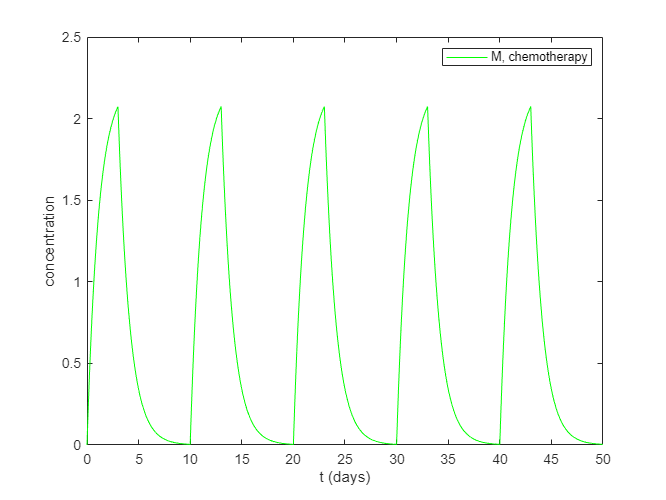


figure(2)
plot(trange,M,'g-')
legend('M, chemotherapy')
xlabel('t (days)')
ylabel('concentration')

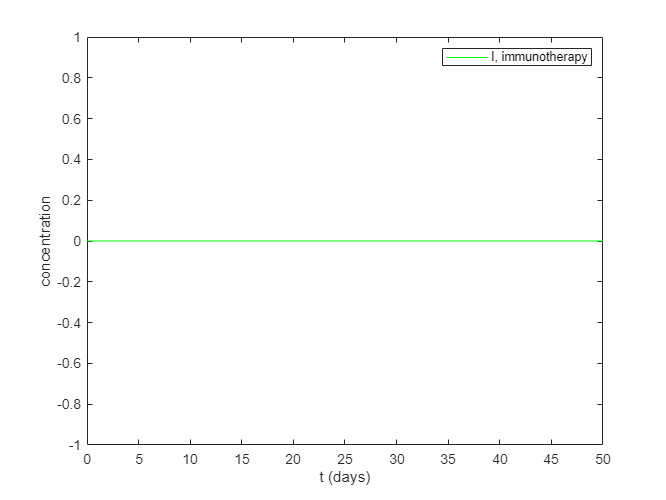


figure(3)
plot(trange,I,'g-')
legend('I, immunotherapy')
xlabel('t (days)')
ylabel('concentration')

function dsolveODEs=solveODEs(t,numerators,params) %% params
%% Define ODEs    
    T = numerators(1); % Tumor Cell Population
    N = numerators(2); % Total NK Cell Population
    L = numerators(3); % Total CD8+ T Cell Population
    C = numerators(4); % Number of Circulating Lymphocytes
    M = numerators(5); % Chemotherapy Blood Concentration 
    I = numerators(6); % Immunotherapy Blood Concentration
    vL_on = params{1}; % TIL drung intervention (mouse)
    vM_on = params{2}; % Chemotherapy drug intervention (nouse & human)
    vI_on = params{3}; % Immunotherapy drug intervention (human)
    patient = params{4};
    scenario = params{5};
    dosing = params{6};

    vL = 0;
    vM = 0;
    vI = 0;
        
    % Potentially time-dependent params   
    if vM_on == 1   
        if t < dosing.Mdose_frequency*dosing.MnumberDoses
            if mod(t, dosing.Mdose_frequency)<dosing.Mdose_duration 
                vM = dosing.Mdose_strength;
            end
        end
    end
            
    if vL_on == 1
        if t >= 7
            if t <= 8
                vL = dosing.Ldose_strength;
            end
        end
    end
                   
 if vI_on == 1 
    if t >= dosing.Istart
        if t <= dosing.Iend
            if mod(t, dosing.Idose_frequency)<0.33 % pulse is not explicitly defined
                vI = dosing.Idose_strength;
            end
        end
    end
    % subsequent IL-2 dosing periods only for Figs 12b-c
    if strcmp(scenario,"Fig12b") || strcmp(scenario,"Fig12c") % day 20-25, then 80-90 
        if t >= 20
            if t <= 25
                if mod(t, dosing.Idose_frequency)<0.33 % pulse is not explicitly defined
                    vI = dosing.Idose_strength;
                end
            end
        end
        if t>= 80
            if t <= 90
                 if mod(t, dosing.Idose_frequency)<0.33 % pulse is not explicitly defined
                    vI = dosing.Idose_strength;
                end
            end
        end    
    end
 end
                        
                        
% Patient parameters from Tables 1 and 2                                                
    if patient == "mouse"
        a = 4.31e-1; % day^-1
        b = 2.17e-8 ;% cells^-1
        c = 7.13e-10 ;% cells^-1day^-1
        d = 8.17 ;% day^-1
        l = 6.57e-1 ;% none
        s = 6.18e-1 ;% none
        e = 1.29e-3 ;% day^-1
        f = 4.12e-2 ;% day^-1
        g = 4.98e-1 ;% day^-1
        h = 2.02e7 ;% cell^2
        p = 1.0e-7 ;% cells^-1day^-1
        m = 2.0e-2 ;% day^-1
        J = 9.96e-1 ;% day^-1
        k = 3.03e5 ;% cell^2
        q = 3.42e-10 ;% cells^-1day^-1
        r1 = 1.1e-7 ;% cells^-1day^-1
        r2 = 3.0e-11 ;% cells^-1day^-1
        u = 1.80e-8 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        alpha = 1.21e5 ;% cellday^-1
        beta = 1.20e-2 ;% day^-1
        gamma = 9.00e-1 ;% day^-1
        % the following values are not in Table 1 but copied from Table 2
        pI = 1.25e-1 ;%day^-1
        gI = 2.00e7;
        muI = 1.00e1;
    elseif patient == "9"  % All parameters Patient 9
        a = 4.31e-1; % day^-1
        b = 1.02e-9; % cells^-1
        c = 6.41e-11; % cells^-1day^-1
        d = 2.34; % day^-1
        e = 2.08e-7; % day^-1
        l = 2.09; % none
        f = 4.12e-2; % day^-1
        g = 1.25e-2; % day^-1
        h = 2.02e7; % cell^2
        J = 2.49e-2; % day^-1
        k = 3.66e7; % cell^2
        m = 2.04e-1; % day^-1
        q = 1.42e-6; % cells^-1day^-1
        p = 3.42e-6; % cells^-1day^-1
        s = 8.39e-2; % none
        r1 = 1.10e-7 ;% cells^-1day^-1
        r2 = 6.50e-11 ;% cells^-1day^-1
        u = 3.00e-10 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        alpha = 7.50e8 ;% cellday^-1
        beta = 1.20e-2 ;% day^-1
        gamma = 9.00e-1 ;% day^-1
        pI = 1.25e-1 ;%day^-1
        gI = 2.00e7;
        muI = 1.00e1;
    elseif patient == "10"
        a = 4.31e-1; % day^-1
        b = 1.02e-9; % cells^-1
        c = 6.41e-11; % cells^-1day^-1
        if scenario == "Fig12a" || scenario == "Fig12b" || scenario == "Fig12c"
            d = 4.88; % day^-1 % the value of 1.88 in the table does not reproduce Figure 12
        else
            d = 1.88; %4.88; % day^-1 
        end
        e = 2.08e-7; % day^-1
        l = 1.81; % none
        f = 4.12e-2; % day^-1
        g = 1.25e-2; % day^-1
        h = 2.02e7; % cell^2
        J = 2.49e-2; % day^-1
        k = 5.66e7; % cell^2
        m = 9.12; % day^-1
        q = 1.59e-6; % cells^-1day^-1
        p = 3.59e-6; % cells^-1day^-1
        s = 5.12e-1; % none
        r1 = 1.10e-7 ;% cells^-1day^-1
        r2 = 6.50e-11 ;% cells^-1day^-1
        u = 3.00e-10 ;% cells^-2day^-1
        KT = 9.00e-1 ;% day^-1
        KNLC = 6.00e-1 ;% day^-1
        alpha = 5.00e8 ;% cellday^-1
        beta = 5e-2;%8.00e-3 ;% day^-1
        gamma = 9.00e-1 ;% day^-1
        pI = 1.25e-1 ;%day^-1
        gI = 2.00e7;
        muI = 1.00e1;
    end
    
    % vaccineParams 
    if scenario == "Fig13b" || scenario == "Fig13c" ||  scenario == "Fig14a" || scenario == "Fig14b"
        if t >= dosing.tVaccine;
            c = 7.131e-9 ;% cells^-1day^-1
            g = 0.5; % day^-1
            J = 1; % day^-1
            d = 15; % day^-1
            s = 0.0019; % none
        end
    end
    
    % time-dependent function D that must be updated at each time step
    D = d*(L/T)^l/(s+(L/T)^l);
        
    % Define the derivatives
    % Population or mass balances are defined for countable numbers of cells 
    % These if-statements are not defined in the manuscript, but they
    % are needed to reproduce the results and prevent unstable/complex
    % solutions when the values approach zero
    if T > 1e-2
        dTdt = a*T*(1-b*T)-c*N*T-D*T-KT*(1-exp(-M))*T;
    else
        dTdt = 0;
    end
    if N > 1e-2
        dNdt = e*C-f*N+g*(T^2/(h+T^2))*N-p*N*T-KNLC*(1-exp(-M))*N;
    else
        dNdt = 0;
    end
    if L > 1e-2
        dLdt = -m*L+J*(D^2*T^2/(k+D^2*T^2))*L-q*L*T+(r1*N+r2*C)*T-u*N*L^2-KNLC*(1-exp(-M))*L+pI*L*I/(gI+I)+vL;
    else
        dLdt = 0;
    end
    
    dCdt = alpha-beta*C-KNLC*(1-exp(-M))*C;
    dMdt = -gamma*M+vM;
    dIdt = -muI*I+vI;
    
    dsolveODEs = [dTdt, dNdt, dLdt, dCdt, dMdt, dIdt]';
end